# Generate figures 7-10 of the paper Robust Tobit Regression  for Censored Observations Using Extended Box-Cox Transformations  

### Marco Riani, Anthony C. Atkinson, Aldo Corbellini and Gianluca Morelli

Remark: we assume that you have FSDA installed, at least version 8.7.7.5

## Esselunga data

% Load Esselunga data, define left right censoring and construct X and y
load Esselunga.mat;

X=Esselunga{:,1:end-1};
y=Esselunga{:,end};

left=0;
right=Inf;

% Do not create postscript figures
prin=0;

## Create Figure 7. LInked yX plot

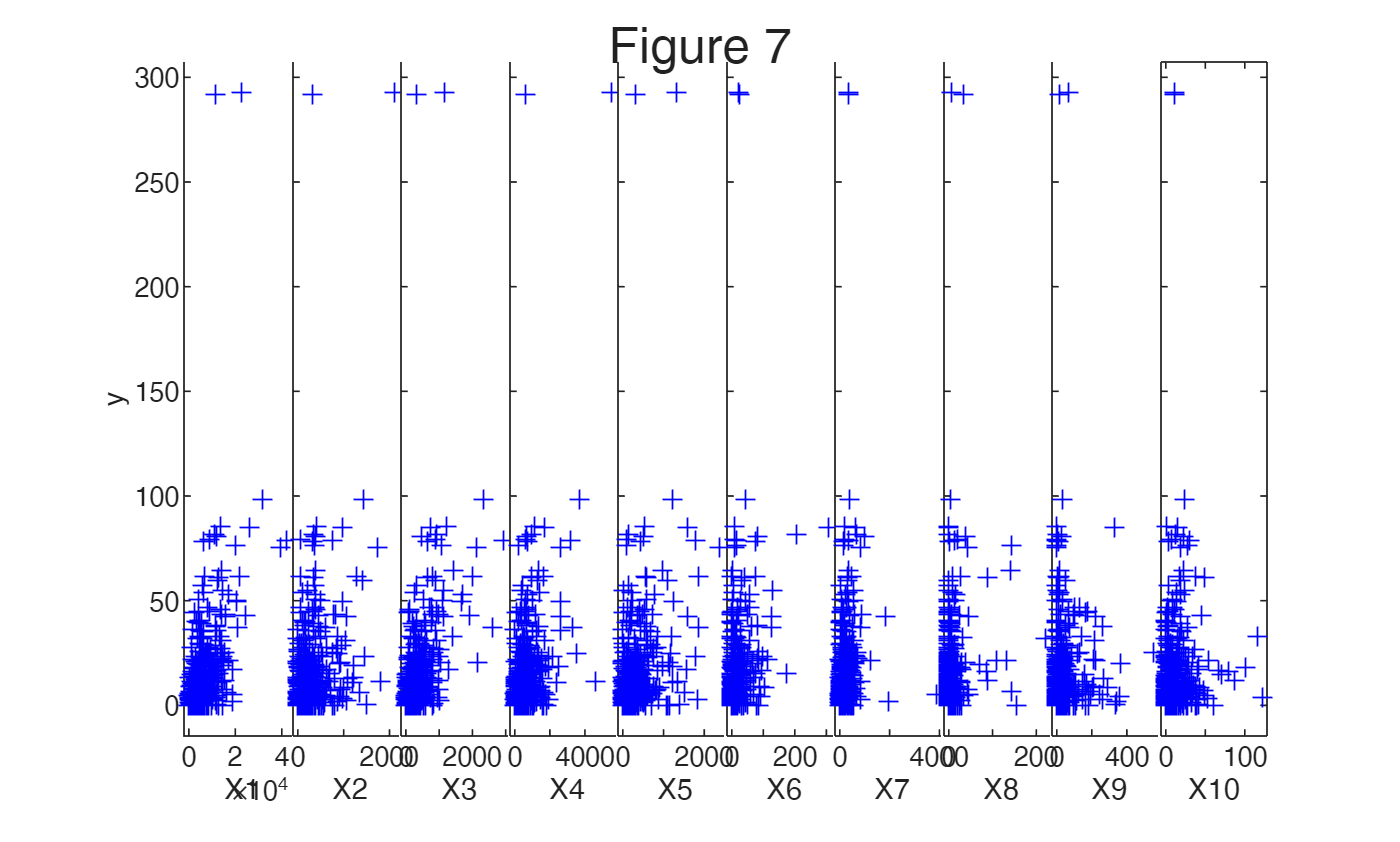

yXplot(y,X);

legend off
if prin==1
    % print to postscript
    print -depsc figs\MD1.eps;
else
    sgtitle('Figure 7')
end

## Prepare input for Figure 8

la=0:0.25:1;
balancedSearch=true;
n=length(y);
selvar=[1 3 6 8];
out=FSRfanCens(y,X(:,selvar),'la',la,'left',left,'right',right, ...
    'family','YJ','init',round(n*0.4),'balancedSearch',balancedSearch,'plots',0);

Total estimated time to complete LMS:  0.02 seconds 
------------------------------
Total estimated time to complete LMS:  0.02 seconds 
------------------------------
Total estimated time to complete LMS:  0.02 seconds 
------------------------------
Total estimated time to complete LMS:  0.02 seconds 
------------------------------
Total estimated time to complete LMS:  0.02 seconds 
------------------------------


## Create Figure 8. Balanced search. Fan plot using the four significant variables.

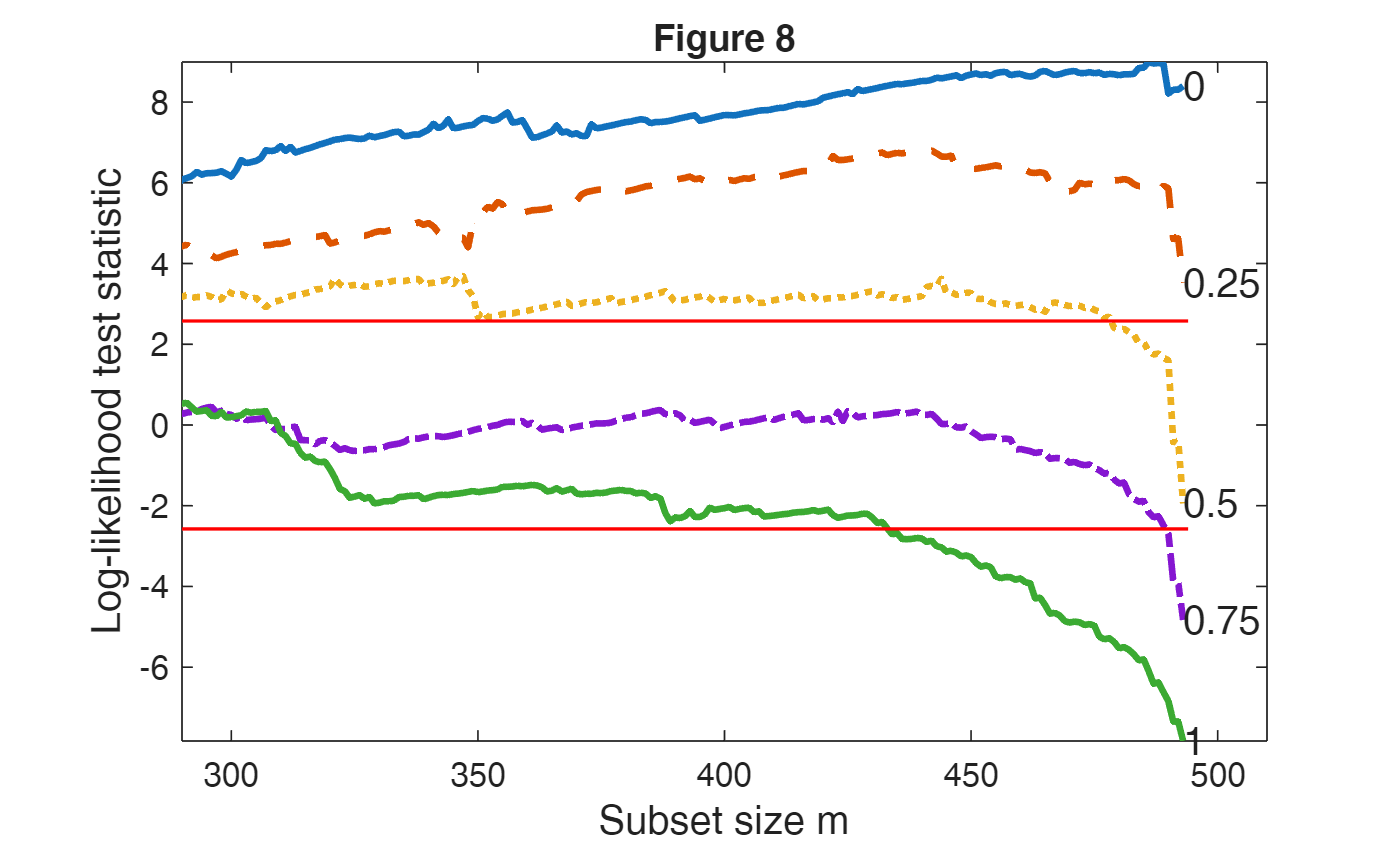

fanplotFS(out);
xlim([290 510])
% fanplotFS(out,'databrush',1,'ylimy',[-20 50])
if prin==1
    title('')
   % print to postscript
    print -depsc figs\MD2.eps;
else
    title('Figure 8')
end

## Prepare input for Figure 9

lambda=0.75;
yf=normYJ(y,1,lambda,'inverse',false,'Jacobian',false);
leftf=normYJ(left,1,lambda,'inverse',false,'Jacobian',false);
rightf=normYJ(right,1,lambda,'inverse',false,'Jacobian',false);
p=size(X,2);
Xf=normYJ(X,(1:p)',lambda*ones(p,1),'inverse',false,'Jacobian',false);
if right==Inf
    rightf=Inf;
end
out5=FSRedaCens(yf,X(:,selvar),0,'left',left,'right',right);

m=100
m=200
m=300
m=400


## Create Figure 9. Unbalanced search using the four significant variables, λ = 0.75, residual monitoring

Remark: the interactive version of this Figure is created by file mainEsselunga_interactive.m

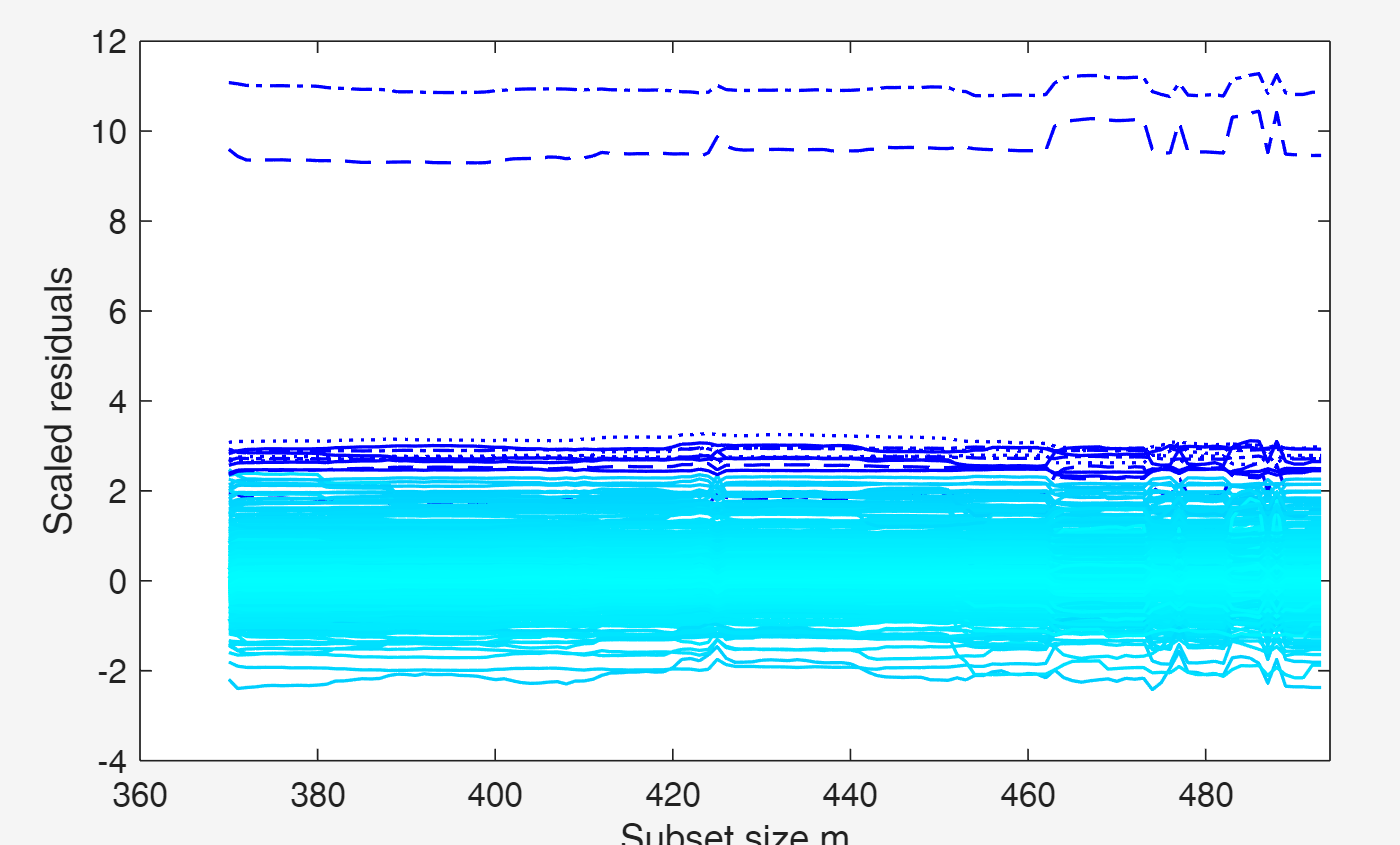

standard=struct;
standard.xlim=[360 n+1];
resfwdplot(out5,'standard',standard,'databrush','','datatooltip','');


if prin==1
    % print to postscript
    print -depsc figs\MD3a.eps;
    print -depsc figs\MD3b.eps;
end

## Table not given in the paper. Analysis of variance table: all variables, all units.

Xtable=Esselunga(:,1:end-1);
disp('λ = 0.75. Analysis of variance table: four variables, all the data')

λ = 0.75. Analysis of variance table: four variables, all the data


outALL=regressCens(yf,Xtable(:,selvar),'left',left,'right',right,'dispresults',true);

Observations:
    Total    LeftCensored    Uncensored    RightCensored
    _____    ____________    __________    _____________

     493         140            353              0      

Coefficients
                    betaout     sebetaout      tout         pval   
                   _________    __________    _______    __________

    (Intercept)      -1.2352       0.52042    -2.3735      0.018009
    X1             0.0004888    0.00012623     3.8723    0.00012255
    X3             0.0079797     0.0016098      4.957    9.8985e-07
    X6              0.059712      0.013189     4.5274    7.5177e-06
    X8              0.037419      

## Create Table 2: λ = 0.75. Analysis of variance table: four variables, no outlier.

% Units 161 and 109 are removed
selunits=(1:n);
selunits=setdiff(selunits,[161 109]);
disp('Table 2: Esselunga data, λ = 0.75. Analysis of variance table: four variables, no outliers.')

Table 2: Esselunga data, λ = 0.75. Analysis of variance table: four variables, no outliers.


regressCens(yf(selunits),Xtable(selunits,selvar),'left',left,'right',right,'dispresults',true);

Observations:
    Total    LeftCensored    Uncensored    RightCensored
    _____    ____________    __________    _____________

     491         140            351              0      

Coefficients
                    betaout      sebetaout      tout        pval   
                   __________    __________    ______    __________

    (Intercept)       -1.2444        0.5222    -2.383      0.017554
    X1             0.00048932    0.00012663    3.8642     0.0001266
    X3              0.0079812     0.0016148    4.9427    1.0632e-06
    X6               0.059737       0.01323    4.5153    7.9481e-06
    X8               0.037429     

## Prepare input for Figure 10 

balancedSearch=false;
selvar=[1 3 6 8];
out=FSRfanCens(y,X(:,selvar),'nsamp',50000,'la',la,'left',left,'right',right, ...
    'family','YJ','init',round(n*0.4),'balancedSearch',balancedSearch,'plots',0);

Total estimated time to complete LMS:  0.76 seconds 
------------------------------
Total estimated time to complete LMS:  0.71 seconds 
------------------------------
Total estimated time to complete LMS:  0.71 seconds 
------------------------------
Total estimated time to complete LMS:  0.70 seconds 
------------------------------
Total estimated time to complete LMS:  0.71 seconds 
------------------------------


## Create Figure 10. Unbalanced search using the four significant variables, λ = 0.75, fan plot

Remark: the interactive version of this Figure is created by file mainEsselunga_interactive.m

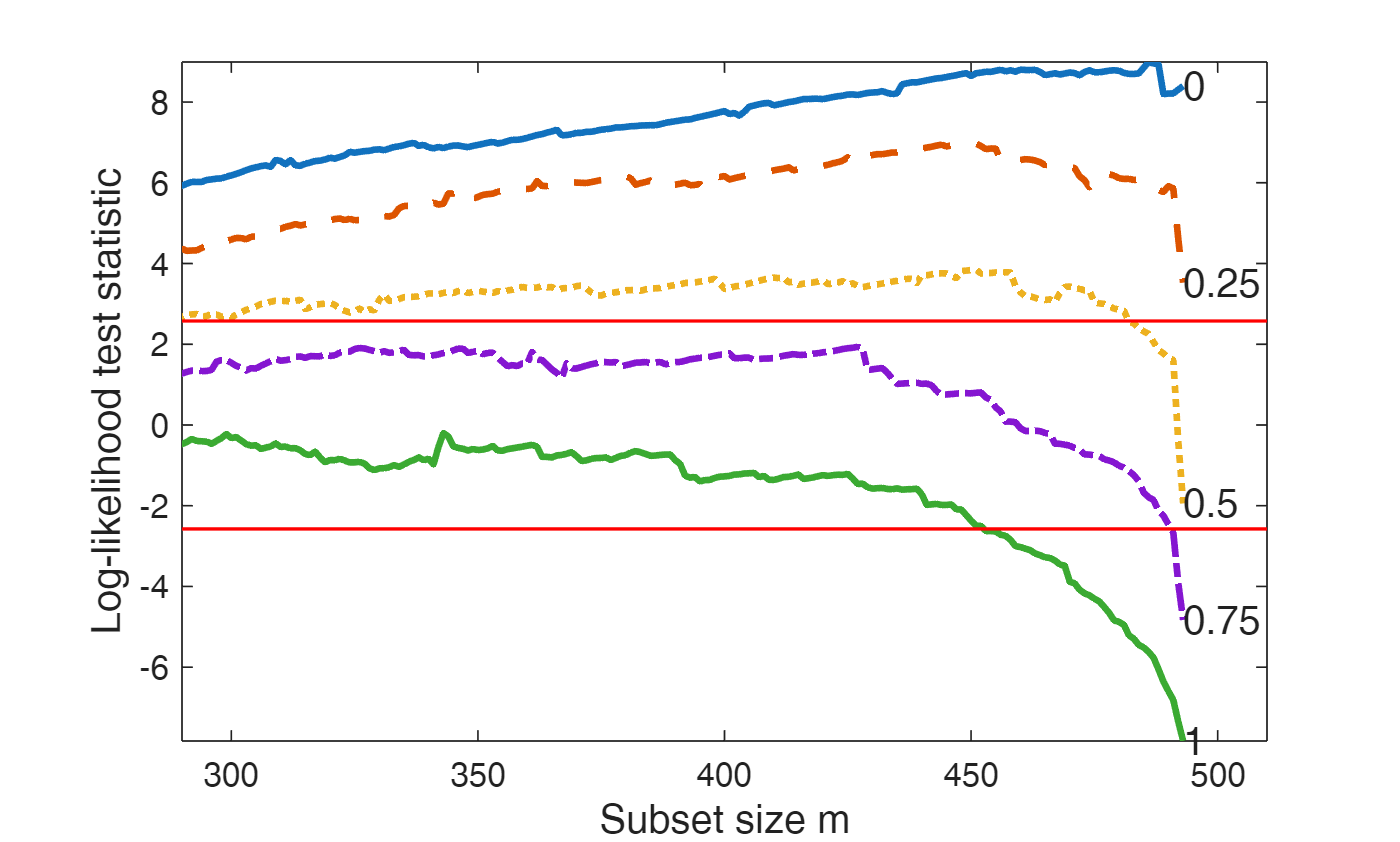

fanplotFS(out,'databrush','', ...
    'titl','','xlimx',[290 510]);


if prin==1
    % print to postscript
    print -depsc figs\MD5a.eps;
    print -depsc figs\MD5b.eps;
end